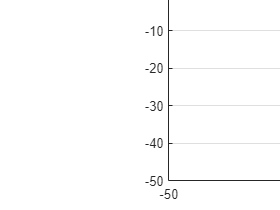

l = [4.7, 10.65, 10.65, 7]; % Longitudes eslabones

L(1) = Link('revolute','alpha',pi/2,'a',0,   'd',l(1),'offset',0,   'qlim',[-3*pi/4 3*pi/4]);
L(2) = Link('revolute','alpha',0,   'a',l(2),'d',0,   'offset',pi/2,'qlim',[-3*pi/4 3*pi/4]);
L(3) = Link('revolute','alpha',0,   'a',l(3),'d',0,   'offset',0,   'qlim',[-3*pi/4 3*pi/4]);
L(4) = Link('revolute','alpha',0,   'a',0,   'd',0,   'offset',0,   'qlim',[-3*pi/4 3*pi/4]);
PhantomX = SerialLink(L,'name','Px');

PhantomX.tool = [0 0 1 l(4); -1 0 0 0; 0 -1 0 0; 0 0 0 1];
ws = [-50 50];

q = deg2rad([45, 45, -60, 30]);
PhantomX.plot(q,'notiles','noname');
hold on
trplot(eye(4),'rgb','arrow','length',15,'frame','0')
axis([repmat(ws,1,2) 0 60])
PhantomX.teach()

M = eye(4);
for i=1:PhantomX.n
    M = M * L(i).A(q(i));
    trplot(M,'rgb','arrow','frame',num2str(i),'length',15)
end


qt = deg2rad([-20, -30, 45, 30]);
Tt = PhantomX.fkine(qt);
% Desacople
T = Tt

T =     0.6645    0.3420   -0.6645   -2.2376
   -0.2418    0.9397    0.2418    0.8144
    0.7071   -0.0000    0.7071   29.1600
         0         0         0    1.0000


Posw = T(1:3,4) - l(4)*T(1:3,3) 

Posw =     2.4137
   -0.8785
   24.2103


% Solucion q1
q1 = atan2(Posw(2),Posw(1));
rad2deg(q1)

ans = -20.0000

% 2R
h = Posw(3) - l(1);
r = sqrt(Posw(1)^2 + Posw(2)^2);

% Codo abajo
the3 = acos((r^2+h^2-l(2)^2-l(3)^2)/(2*l(2)*l(3)));
the2 = atan2(h,r) - atan2(l(3)*sin(the3),l(2)+l(3)*cos(the3));

q2d = -(pi/2-the2);
q3d = the3;

% Codo arriba
the2 = atan2(h,r) + atan2(l(3)*sin(the3),l(2)+l(3)*cos(the3));
q2u = -(pi/2-the2);
q3u = -the3;

disp(rad2deg([q2d q3d; q2u q3u]))

  -30.0000   45.0000
   15.0000  -45.0000




%q4

% Codo arriba
T03d = PhantomX.A([1 2 3],[q1 q2d q3d])

T03d =    -0.2432   -0.9077   -0.3420    2.4137
    0.0885    0.3304   -0.9397   -0.8785
    0.9659   -0.2588    0.0000   24.2103
         0         0         0    1.0000


R_3Td = (T03d(1:3,1:3))'*T(1:3,1:3)

R_3Td =     0.5000   -0.0000    0.8660
   -0.8660   -0.0000    0.5000
    0.0000   -1.0000   -0.0000


q4d = atan2(R_3Td(1,1),-R_3Td(2,1));
rad2deg(q4d)

ans = 30.0000

% Codo abajo
T03u = PhantomX.A([1 2 3],[q1 q2u q3u]);
R_3Tu = (T03u(1:3,1:3))'*T(1:3,1:3);
q4u = atan2(R_3Tu(1,1),-R_3Tu(2,1));
rad2deg(q4u)

ans = 75.0000


%invkine
qinv(1,1:4) = [q1 q2u q3u q4u]

qinv =    -0.3491    0.2618   -0.7854    1.3090
   -2.7925   -0.6109    0.2618    2.3562


qinv(2,1:4) = [q1 q2d q3d q4d];
disp(rad2deg(qinv))

  -20.0000   15.0000  -45.0000   75.0000
  -20.0000  -30.0000   45.0000   30.0000

